clear; clc;

## Image Negative

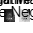

f = imread('mammogram.tif');	% read original image
L = 256;						% Max value of pixel value 2^8
T = 255 - f;					% compute image negative
subplot(1,2,1), imshow(f), title('original image');
subplot(1,2,2), imshow(T), title('negative image');
sgtitle("Image Negative");

clear;

## Linear Streching

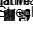

f = imread('pollen.tif');										% read original image
figure
T = imadjust(f, [20 70]/255, [0 255]/255, 1);					% compute linear streching
subplot(1,2,1), imshow(f), title('original image');	
subplot(1,2,2), imshow(T), title('negative image');
sgtitle("Linear Streching old");

% based on max and min values from image
img_max = max(max(f))

img_max = uint8
83

img_min = min(min(f))

img_min = uint8
13

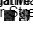

low_in		= double(img_min);
high_in		= double(img_max);
low_out		= 0;
high_out	= 255;
T = imadjust(f, [low_in high_in]/255, [low_out high_out]/255, 1);					% compute linear streching
figure
subplot(1,2,1), imshow(f), title('original image');	
subplot(1,2,2), imshow(T), title('negative image');
sgtitle("Linear Streching");

% based on 2nd and 98 percentile from image
img_max = prctile(prctile(f,98),98)

img_max = uint8
77

img_min = prctile(prctile(f,2),2)

img_min = uint8
13

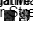

low_in		= double(img_min);
high_in		= double(img_max);
low_out		= 0;
high_out	= 255;
T = imadjust(f, [low_in high_in]/255, [low_out high_out]/255, 1);					% compute linear streching
figure
subplot(1,2,1), imshow(f), title('original image');	
subplot(1,2,2), imshow(T), title('negative image');
sgtitle("Linear Streching");

clear;

## Contrast Streching

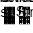

f = imread('bone-scan.tif'); 
f1 = double(f); % convert f to double for arithmetic operations
m = mean2(f1); % parameter m
E = 2; % parameter E 
u = (f1 + eps);
g = 1./(1 + (m./ u) .^ E); % contrast stretching operation
g = im2uint8(g); % convert image to 8-bit gray scale
figure
subplot(1,2,1), imshow(f), title('original image');
subplot(1,2,2), imshow(g), title('contrast stretching');
sgtitle('Contrast Streching')

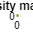


figure
stem(g, u, '.'); % plot the histogram
grid, xlabel('T(u)'), ylabel('u')
title('intensity mapping');

clear;

## Image histogram